# Actividad 8.1 (Modelado Cinemático de Piernas)

### Jhonatan Yael Martinez Vargas

### Instrucciones:

**Obtener** la matriz de  transformación **homogénea  T ** de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

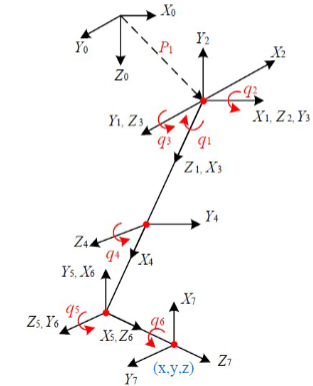

Dada la configuración propuesta en la imagen, lo primero que se debe de hacer es las matrices de transformación homogénea, en este caso al no tener especificadas las medidas de las tramas, se asume que todas tienen la misma longitud, en este caso 4 unidades.

clear all
close all
clc

m_H0 = SE3;

% Apartir de este momento cada junta tiene que realizar dos rotaciones en diferentes ejes por
% lo que se crean dos matrices de rotacion continuas para cada una de estas

% Junta 1 a junta 2
m_H1 = SE3(roty(pi/2), [0,0,0])

 

m_H1 = 
    0.9996         0    0.0274         0
         0         1         0         0
   -0.0274         0    0.9996         0
         0         0         0         1


m_H2 = SE3(rotz(-pi/2), [0,0,0])

 

m_H2 = 
    0.9996    0.0274         0         0
   -0.0274    0.9996         0         0
         0         0         1         0
         0         0         0         1



% Junta 2 a junta 3
m_H3 = SE3(roty(-pi/2), [0,0,0])

 

m_H3 = 
    0.9996         0   -0.0274         0
         0         1         0         0
    0.0274         0    0.9996         0
         0         0         0         1


m_H4 = SE3(rotz(-pi/2), [0,0,0])

 

m_H4 = 
    0.9996    0.0274         0         0
   -0.0274    0.9996         0         0
         0         0         1         0
         0         0         0         1



% Junta 3 a junta 4
m_H5 = SE3(roty(0), [2,0,0])

 

m_H5 = 
         1         0         0         2
         0         1         0         0
         0         0         1         0
         0         0         0         1



% Junta 4 a junta 5
m_H6 = SE3(rotz(-pi/2), [2,0,0])

 

m_H6 = 
    0.9996    0.0274         0         2
   -0.0274    0.9996         0         0
         0         0         1         0
         0         0         0         1



% Junta 5 a junta 6
m_H7 = SE3(rotz(pi/2), [0,0,0])

 

m_H7 = 
    0.9996   -0.0274         0         0
    0.0274    0.9996         0         0
         0         0         1         0
         0         0         0         1


m_H8 = SE3(rotx(pi/2), [0,0,0])

 

m_H8 = 
         1         0         0         0
         0    0.9996   -0.0274         0
         0    0.0274    0.9996         0
         0         0         0         1



% Junta 6 a junta 7
m_H9 = SE3(roty(0), [0,0,2])

 

m_H9 = 
         1         0         0         0
         0         1         0         0
         0         0         1         2
         0         0         0         1


Posteriormente lo que se realiza es definir a las matrices de transformacion globales, las cuales son el resultado del producto de dos tramas.

%Matriz de transformación homogenea global de 4 a 0 
m_H20 = m_H1 * m_H2;
m_H30 = m_H20 * m_H3;
m_H40 = m_H30 * m_H4;
m_H50 = m_H40 * m_H5;
m_H60 = m_H50 * m_H6;
m_H70 = m_H60 * m_H7;
m_H80 = m_H70 * m_H8;
m_H90 = m_H80 * m_H9;

Finalmente para temas de simulacion se establecen los limites del entorno en el cual se va deserrollar la simulación

plot3(0, 0, 0); axis([-6 6 -6 6 -6 6]); grid on;
hold on;

Se realizan las animaciones para cada una de las tramas:

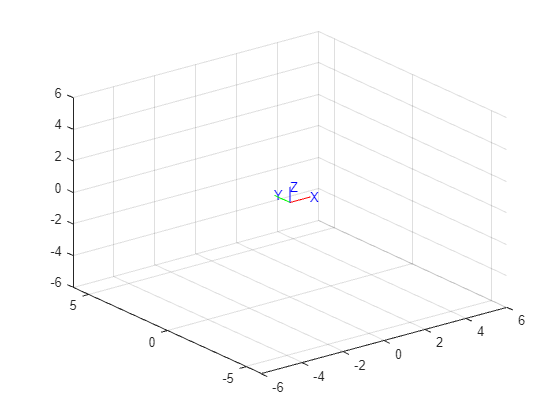

trplot(m_H0,'rgb','axis', [-6 6 -6 6 -6 6])

% Matriz de transformacion final
disp(m_H90)

       0.9985   0.05477 -0.001492     3.991
     -0.05479    0.9981  -0.02662   -0.2724
    3.089e-05   0.02666    0.9996     1.999
            0         0         0         1


Aqui lo que se puede apreciar es el valor numerico que representa la matriz de transformacion final